# Perfomance of first principle model

Description: 

Demonstration of first principle model performance fitted to different valve and damping ajustments (fault states).

There are 2 examples for each fault state:

    1. Valve1 fault

    2. Valve2 fault

    3. Damper upper

    4. Damper bottom

 Author: Artyom Voronin

 Brno, 2021

clc; clear all; close all;

#### Load parameters, model and dataensemble

Models were fitted to different fault codes represent different system behavior.

Global parameters to change during simulation:

global C_A_in C_A_out C_B_in C_B_out P_cr b_small_bot b_small_up SmallDamper_upper SmallDamper_bottom

run('params.m')
addpath("./functions/")
open("model_equation_simply_valves.slx")
fault_codes = ["1100001","1103204", "1103203", "1101607", "1101608", "1100220", "1100223", "1100816", "1100817"]

fault_codes = 1×9 string array
    "1100001"    "1103204"    "1103203"    "1101607"    "1101608"    "1100220"    "1100223"    "1100816"    "1100817"


Data was load from datastore, but for further experiments, members can be load from local .mat file.

load_datastore = 0

load_datastore = 0

Extract members from dataensemble with different faultcodes:

if load_datastore
    run('../utils/import_only_signals_datastore.m'); datastore
    reset(datastore)
    members = extract_members(fault_codes, datastore)
else
    members = load("data/members.mat").members
end

members = 1×9 cell array
    {1×24 table}    {1×24 table}    {1×24 table}    {1×24 table}    {1×24 table}    {1×24 table}    {1×24 table}    {1×24 table}    {1×24 table}


Import Input signal and time for model

[t, u1, u2] = input_signals(members{1,1});

Fault_code: 1100001 
Parameters: 
valve1: 2, valve2: 4 
damp_small_up: 4, damp_small_bot: 6 
damp_large_up: 0, damp_large_bot: 0 


Healthy system behavior 


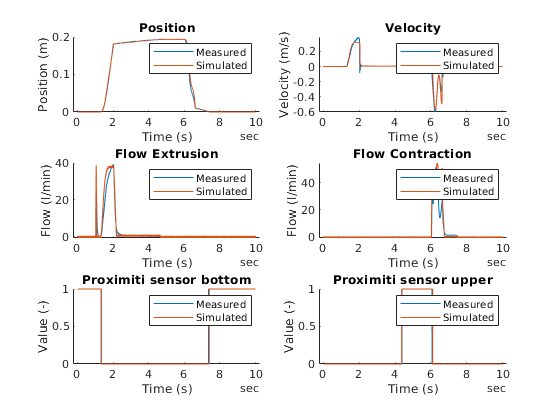

Fault_code: 1103204 
Parameters: 
valve1: 2, valve2: 6 
damp_small_up: 4, damp_small_bot: 6 
damp_large_up: 0, damp_large_bot: 0 


Valve on B chamber changed value 


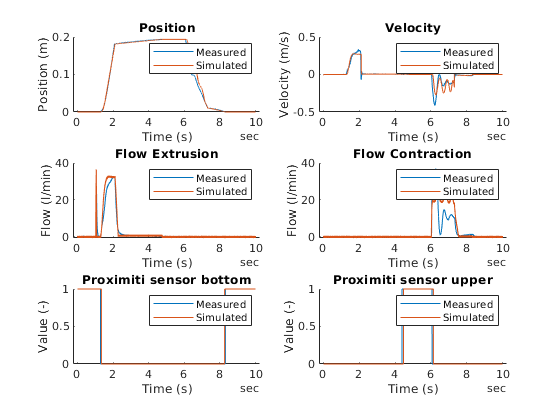

Fault_code: 1103203 
Parameters: 
valve1: 2, valve2: 2 
damp_small_up: 4, damp_small_bot: 6 
damp_large_up: 0, damp_large_bot: 0 


Valve on B chamber changed value 


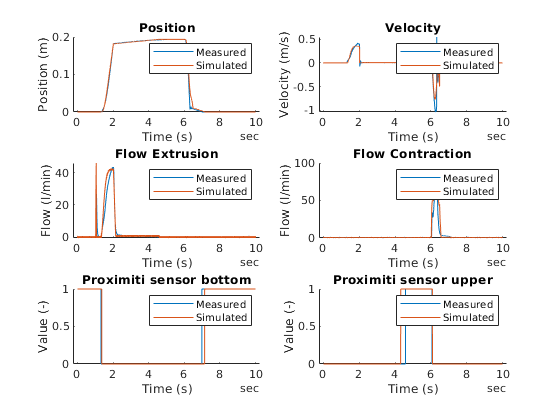

Fault_code: 1101607 
Parameters: 
valve1: 0, valve2: 4 
damp_small_up: 4, damp_small_bot: 6 
damp_large_up: 0, damp_large_bot: 0 


Valve on A chamber changed value 


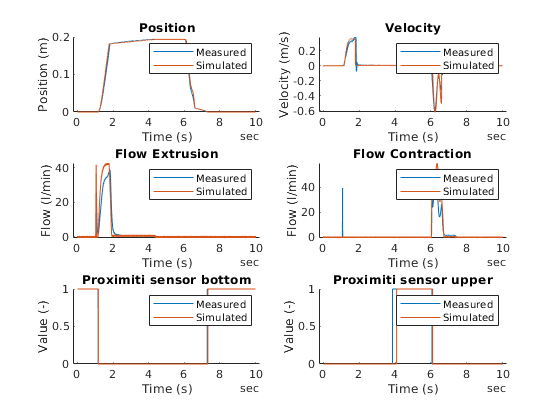

Fault_code: 1101608 
Parameters: 
valve1: 4, valve2: 4 
damp_small_up: 4, damp_small_bot: 6 
damp_large_up: 0, damp_large_bot: 0 


Valve on A chamber changed value 


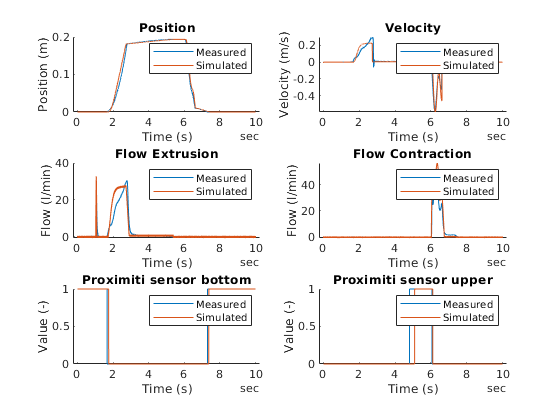

Fault_code: 1100220 
Parameters: 
valve1: 2, valve2: 4 
damp_small_up: 2, damp_small_bot: 6 
damp_large_up: 0, damp_large_bot: 0 


Upper small damper changed value 


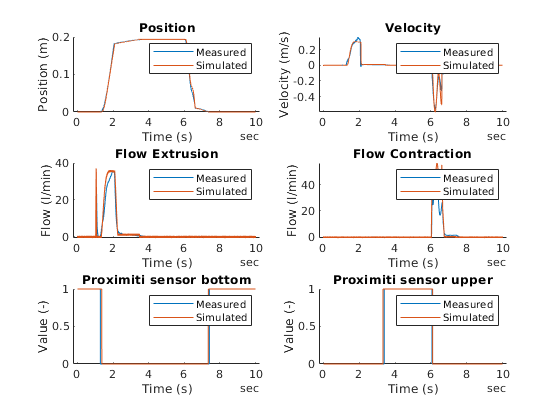

Fault_code: 1100223 
Parameters: 
valve1: 2, valve2: 4 
damp_small_up: 6, damp_small_bot: 6 
damp_large_up: 0, damp_large_bot: 0 


Upper small damper changed value 


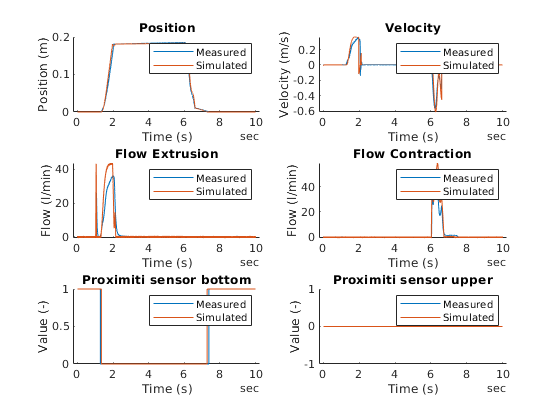

Fault_code: 1100816 
Parameters: 
valve1: 2, valve2: 4 
damp_small_up: 4, damp_small_bot: 5 
damp_large_up: 0, damp_large_bot: 0 


Bottom small damper changed value 


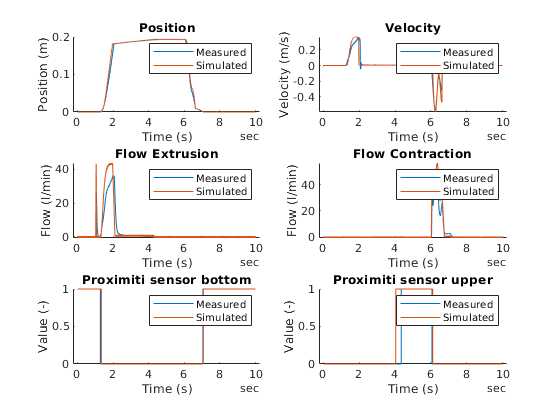

Fault_code: 1100817 
Parameters: 
valve1: 2, valve2: 4 
damp_small_up: 4, damp_small_bot: 7 
damp_large_up: 0, damp_large_bot: 0 


Bottom small damper changed value 


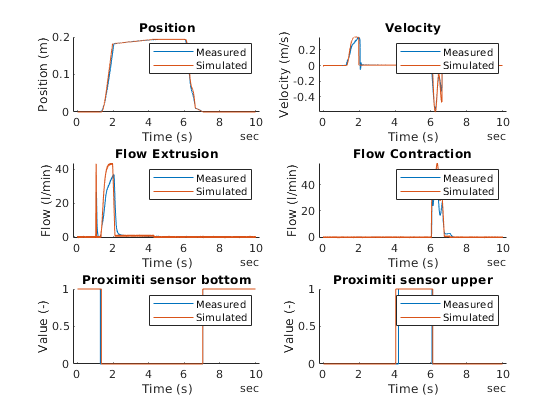

for member = members
    config_print(member{1,1})
    data_measured = extract_signals_from_member(member{1,1});
    data_simulated = simulate_model(member{1,1});
    plot_measured_simulated_data(data_measured, data_simulated)
end